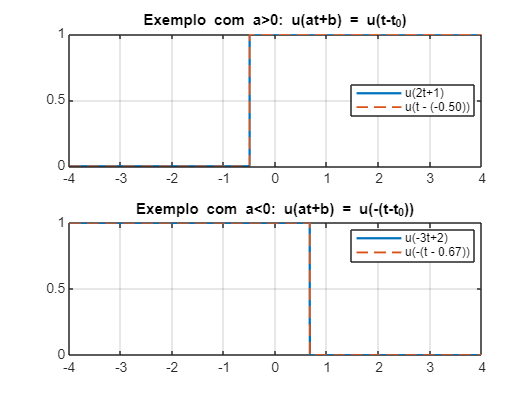

% Unit step (Heaviside)
u = @(t) double(t >= 0);
t = -4:0.001:4;

%% Exemplo 1: a > 0  (sem reflexão, só shift)
a1 = 2; 
b1 = 1;
t0_1 = -b1/a1;     
figure;
subplot(2,1,1);
plot(t, u(a1*t + b1), 'LineWidth', 1.5); hold on;
plot(t, u(t - t0_1), '--', 'LineWidth', 1.2);
grid on;
legend('u(2t+1)', sprintf('u(t - (%.2f))', t0_1), ...
       'Location','best');
title('Exemplo com a>0: u(at+b) = u(t-t_0)');

%% Exemplo 2: a < 0  (reflexão + shift)
a2 = -3;
b2 = 2;
t0_2 = -b2/a2;     
subplot(2,1,2);
plot(t, u(a2*t + b2), 'LineWidth', 1.5); hold on;
plot(t, u(-(t - t0_2)), '--', 'LineWidth', 1.2);
grid on;
legend('u(-3t+2)', sprintf('u(-(t - %.2f))', t0_2), ...
       'Location','best');
title('Exemplo com a<0: u(at+b) = u(-(t-t_0))');